# Classification of Limb Movements using EMG Data

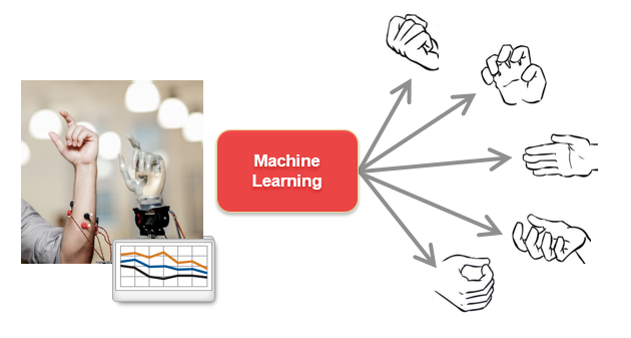

The goal of this analysis is to develop a classifier to identify type of movement from EMG signal for prosthetics development. We will process EMG sensor data with known actions being taken and then train a classification algorithm to make predictions given new sensor readings.

clear; clc; close all; gcp;

## Import and Preprocess Data

First, we need to import the data from each of the different files into one table. A convenient way to do this is with `datastore`. Datastores allow you to point at a file, or collection of files as we have here, specify the formatting and then read all or a portion of the data in.

trainds = datastore('.\Data\TrainingData\*.csv');
trainds.SelectedFormats{9} = '%C'; % Categorical
nsensors = 8; % Eight sensors
preview(trainds)

ans = 8×9 table
    rawDataOut1    rawDataOut2    rawDataOut3    rawDataOut4    rawDataOut5    rawDataOut6    rawDataOut7    rawDataOut8      Action  
    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________
       36838          37549          38656          38854          38616          38933          38893          59486       Chuck Grip
       40395          38024          38854          39723          39644          39763          39684          56561       Chuck Grip
       41344          39091          38893          40118          40395          40158          39723          49407       Chuck Grip
   

Read all of the data in one shot.

TrainData = readall(trainds);

We will eventually visualize the signals colored by action. To do this, we first create a vector of time information.

fs = 1800; % Hz
dt = 1/fs; % Discrete time element
t = seconds(0:dt:dt*(height(TrainData)-1));

naction = mode(countcats(TrainData.Action)); % Samples in most common action
blocksize = naction/gcd(naction, fs);

## Visualize the Raw Data

Then we use the grouped scatter plot to visualize the signals whos actions are labeled with color.

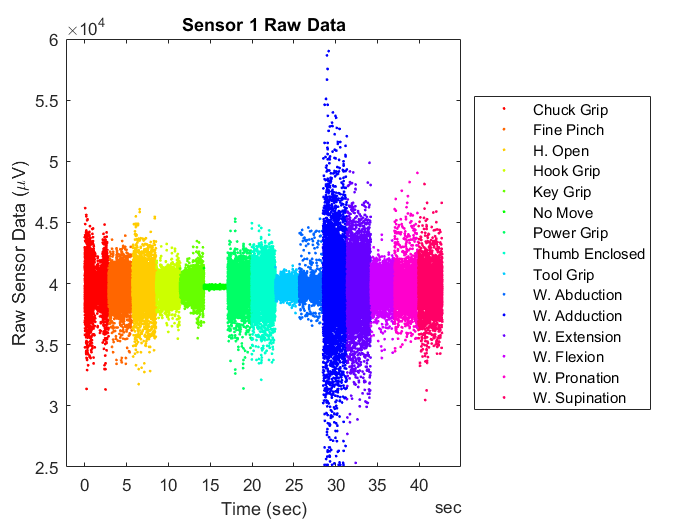

gscatter(t,TrainData{:,1},TrainData.Action,[],[],[],'off')
title('Sensor 1 Raw Data')
xlabel('Time (sec)')
ylabel('Raw Sensor Data (\muV)')
legend(categories(TrainData.Action),'Location','EastOutside')

## What are the Differentiating Features Between Actions?

Could start by doing something very simple.  We could simply calculate some statistic measurements of small chunks of consecutive data, regardless of how they are distributed in time, for example take `max`, `min`, and `std` values and use these as parameters in a machine learning model.

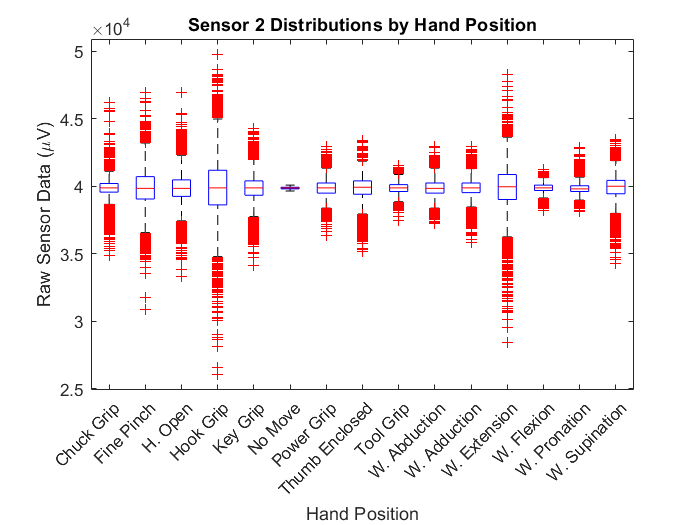

boxplot(TrainData.rawDataOut2,TrainData.Action);
a = gca;
a.XTickLabelRotation = 45;
title('Sensor 2 Distributions by Hand Position')
xlabel('Hand Position')
ylabel('Raw Sensor Data (\muV)')

## Use Signal Processing to Get More Features

For signals that are statistically similar, it is no longer sufficient to rely on simple statistics to differentiate between the signals.  This is when signal processing can play a key role.  Let's first remove the DC offset and rectify the raw signal, common tasks in EMG processing.  

**Remove DC offset in the signal**

Use the `detrend` to remove the DC offset from the EMG signal in preparation for signal processing. For more information on `detrend`, see `doc('detrend')`.

data_DC = detrend(TrainData{:,1:end-1});

**Full-Wave Rectification**

Half- or full-wave rectification is a common step in processing EMG signals. We will do this by taking the absolute value of the signal. 

rec_data = abs(data_DC);

**Visualize the Rectified Signal**

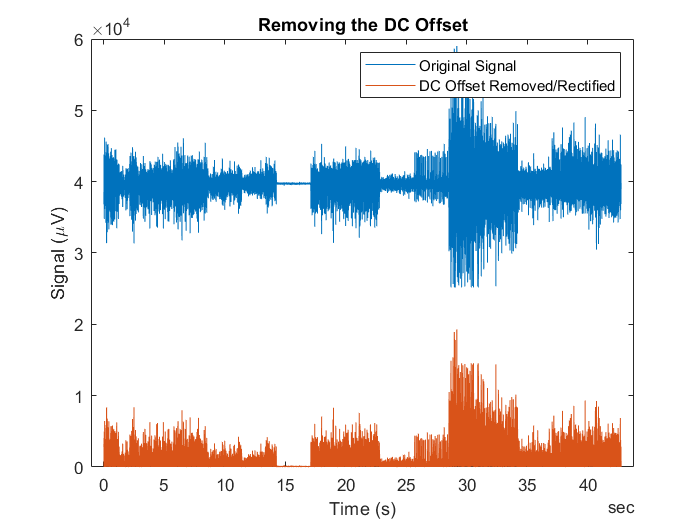

plot(t,TrainData{:,1},t,rec_data(:,1))
title('Removing the DC Offset')
xlabel('Time (s)')
ylabel('Signal (\muV)')
legend('Original Signal','DC Offset Removed/Rectified')

## Signal Analyzer

Where do we start to find features for machine learning?  There are many possible waveform parameters that can be explored and extracted.  Let's use the Signal Analyzer App to visualize and explore the differences between a few signals to get some ideas for differentiating between the various actions.

wsupination = data_DC(TrainData.Action == 'W. Supination',1);
keygrip = data_DC(TrainData.Action == 'Key Grip',1);
nomove = data_DC(TrainData.Action == 'No Move',1);

Open the Signal Analyzer App from the toolstrip or with the following command.

`signalAnalyzer`

## Finding the Linear Envelope

Another common approach to processing EMG signals is to take the linear envelope. Let's look at two methods for finding the linear envelope: using a low pass filter, and using RMS.

**Option 1 - Low Pass Filter **

Let's first try out the Filter Designer App to apply a low-pass filter to the rectified signal in order to obtain the signal envelope.

lp = LPFilter;
env1 = filter(lp,rec_data);

**Option 2 - RMS Envelope**

A common approach to obtaining the linear envelope is via RMS.  

[env2,~] = envelope(rec_data,blocksize*3,'rms');

**Plot and Compare**

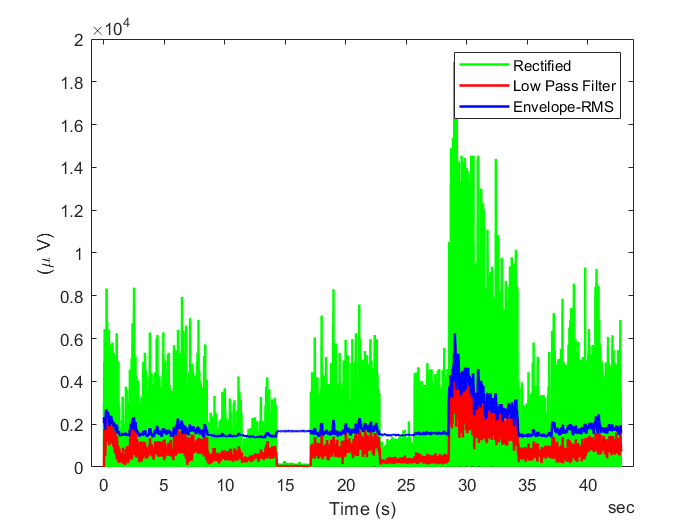

clf
plot(t,rec_data(:,1),'g',t,env1(:,1),'r',t,env2(:,1), 'b','LineWidth',1.5);
xlabel('Time (s)'); ylabel('(\mu V)');
legend('Rectified','Low Pass Filter', 'Envelope-RMS');

## Other Features?

Let's consider the frequency domain. Some other common parameters used in EMG analysis are 

- Amplitude Parameters - peak EMG value, mean EMG value, area under the EMG amplitude (mathematical integral)

- Frequency Parameters - peak power, total power (area under the spectrum curve), mean frequency, median frequency

**Total Power Calculation**

Let's try getting total power as a feature for this 

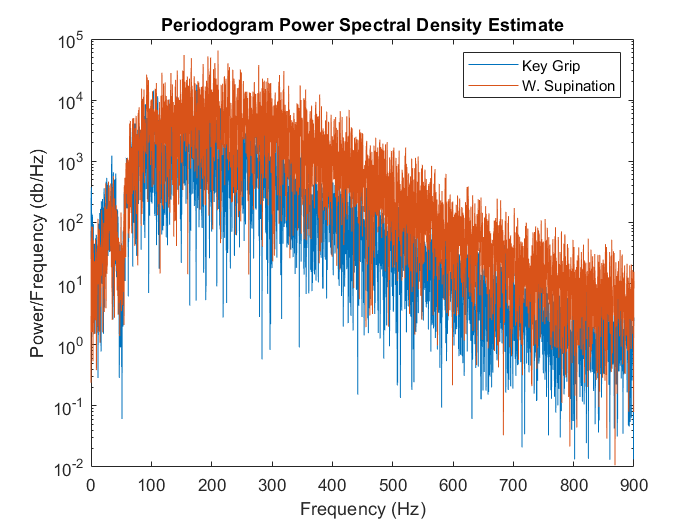

clf
[pxx,f] = periodogram([keygrip,wsupination],[],[],fs);
semilogy(f,pxx)
title('Periodogram Power Spectral Density Estimate')
ylabel('Power/Frequency (db/Hz)')
xlabel('Frequency (Hz)')
legend('Key Grip','W. Supination')

totalpower = trapz(f,pxx,1);
fprintf('Total power in key grip signal is %f.\n',totalpower(1))

Total power in key grip signal is 479787.237235.


fprintf('Total power in w. supination signal is %f.\n',totalpower(2))

Total power in w. supination signal is 2013258.536915.


## Train a Classifier

Now let's try some machine learning. There are many features from time and frequency domain we can exploit as predictors for the EMG signal. For now, let's use the envelope we calculated before, signal variance, and total power under the spectrum curve.

edit generateFeatures

funs = @(x)generateFeatures(x,fs);
traindataSP = blockproc(TrainData{:,1:nsensors},[blocksize nsensors],@(block)funs(block.data),'UseParallel',true);
traindataSP = array2table(traindataSP);
traindataSP.Properties.VariableNames = makeVariableNames({'var';'env';'tpwr'}, nsensors);
traindataSP.Action = TrainData.Action(1:blocksize:end);

## Automate Creation of the Classifier

Now that we have our training dataset, the next step is to choose a machine learning algorithm to be trained.  How do you choose a learning algorithm? In this datastorecase, we will use the Classification Learner App to explore various learners until we find one that yield satisfactory results.

`classificationLearner`

An added benefit to using the Classification Learner is that it can generate the training code in the event I want to retrain the model or incorporate new data.

[classifier, validationAccuracy] = trainSPClassifier(traindataSP);

disp(['Accuracy is ', num2str(validationAccuracy * 100) ,'%'])

Accuracy is 94.3704%


## Predict Activity for Test Dataset

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.  First, apply all of the same preprocessing steps to the new data.

testds = datastore('.\Data\TestingData\*.csv');
testds.SelectedFormats{9} = '%C';
TestData = readall(testds);
testdataSP = blockproc(TestData{:,1:nsensors},[blocksize nsensors],@(block)funs(block.data),'UseParallel',true);

Then make prediction and compare to known results.

[PredictedAction,score] = predict(classifier.ClassificationEnsemble,testdataSP);
disp(['Accuracy is ', num2str(nnz(PredictedAction==TestData.Action(1:blocksize:end))./numel(PredictedAction)*100),'%'])

Accuracy is 79.8519%


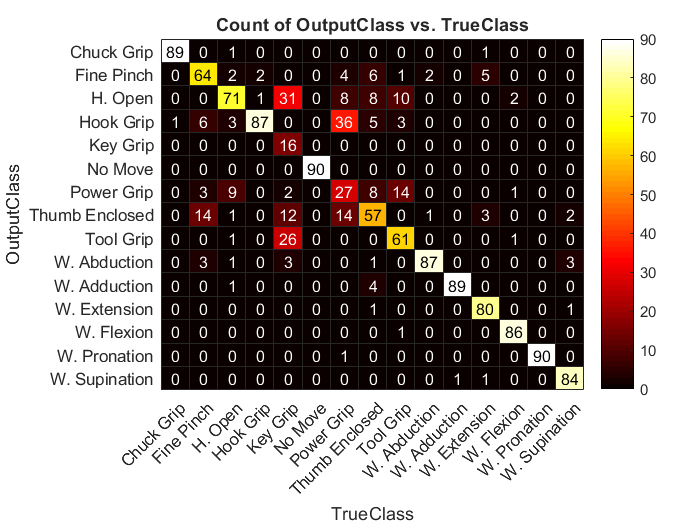

resultstbl = table(PredictedAction,TestData.Action(1:blocksize:end),'VariableNames',{'OutputClass','TrueClass'});
h = heatmap(resultstbl,'TrueClass','OutputClass');
h.Colormap = hot;

## Model Refinement: Number of Trees?

How many trees do we really need? The model provides an out-of-bag loss function for calculating how much more error there is by leaving out additional trees

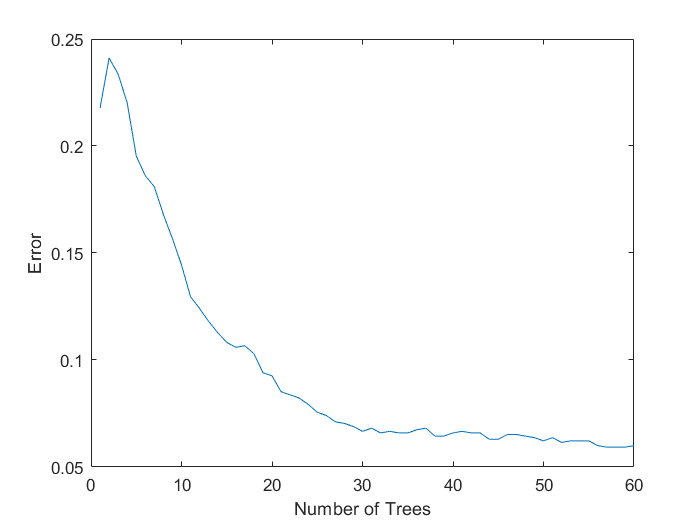

plot(oobLoss(classifier.ClassificationEnsemble,'mode','cumulative'))
xlabel('Number of Trees')
ylabel('Error')

## Model Refinement: Predictor Importance?

Which predictors are the most important to the model? The `predictorImportance` metric will tell us how much more error there is if that predictor was to be removed.

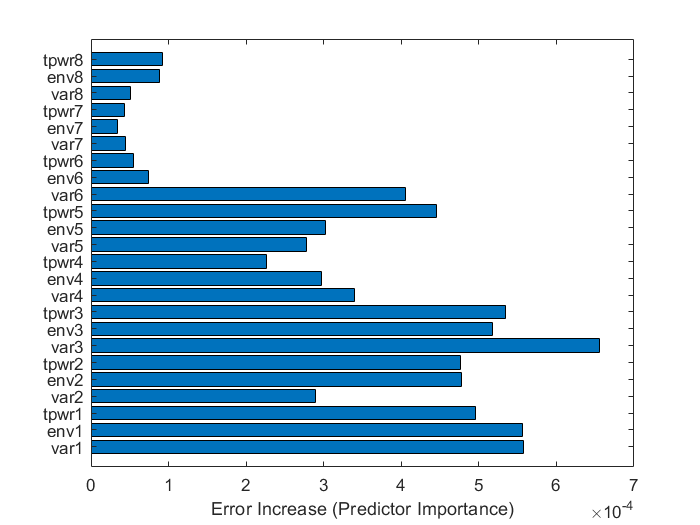

predimp = predictorImportance(classifier.ClassificationEnsemble);
barh(predimp)
ax = gca;
ax.YTick = 1:numel(predimp);
ax.YTickLabel = classifier.RequiredVariables;
xlabel('Error Increase (Predictor Importance)')

## Use the Classifier

Let's package up the classifier into a function that takes raw signal data from our 8 channels and outputs a classification for that chunk of signal.

x = TestData{1:57,1:nsensors};
classifyEMG(x,fs)

ans = 'Chuck Grip'

*Copyright 2017 The MathWorks, Inc.*